Assignment 3 - Loop Closure

Complete Implementation : 

Position Analysis

clear all ;
clf('reset')

l1 = 400e-3;
l2 = 200e-3;
o2 = pi/3;
L = 700e-3;

X = [500e-3;20/180*pi];
tol = 1e-6;
change = [inf;inf];

iter = 0;
max_iter = 100;
while((sum(abs(change)) >= tol))
    l3 = X(1);
    o3 = X(2);
    J = [-cos(o3),l3*sin(o3);-sin(o3),-l3*cos(o3)];
    F = [l1+l2*cos(o2)-l3*cos(o3);l2*sin(o2)-l3*sin(o3)];
    if(abs(det(J))<1e-6 )
        fprintf("Approaching singular jacobian")
        break;
    end
    change = -1*pinv(J)*F;
    X = X +change;
    iter = iter + 1;
    if(iter>=max_iter)
        fprintf("overflow")
        break;
    end
end

l3 = X(1)

l3 = 0.5292

o3  = X(2)

o3 = 0.3335

Velocity(Angular Analysis)

J = [-cos(o3),l3*sin(o3);-sin(o3),-l3*cos(o3)];
w2 = -7*pi;
B = w2*[l2*sin(o2);-l2*cos(o2)];
X1 = pinv(J) * B

X1 =     2.8793
   -6.2832


Acceleration Analysis

J = [-cos(o3),l3*sin(o3);-sin(o3),-l3*cos(o3)];
w2 = -7*pi;
w3 = X1(2);
l3_1 = X1(1);
C = w2*w2*[l2*cos(o2);l2*sin(o2)] + 2*l3_1*w3*[-sin(o3);cos(o3)] + w3*w3*[-l3*cos(o3);-l3*sin(o3)];
X2 = pinv(J)*C

X2 =   -52.2250
  -51.2840


Analysis for the slider

L3 = L-l3;
l5 = 200e-3;
l4 = 300e-3;

Y = [70e-3;60/180*pi];
tol = 1e-9;
change = inf;

iter = 0;
max_iter = 100;
while(sum(abs(change)) >= tol)
    s = Y(1);
    o4 = Y(2);
    J = [0,l4*sin(o4);1,-l4*cos(o4)];
    F = [l2*cos(o2) + L3*cos(o3)-l4*cos(o4)-l5;l2*sin(o2) + L3*sin(o3)-l4*sin(o4)+s];
    if(abs(det(J))<1e-6 )
        fprintf("Approaching singular jacobian")
        break;
    end
    change = -1*pinv(J)*F;
    Y = Y +change;
    iter = iter + 1;
    if(iter>=max_iter)
        fprintf("overflow")
        break;
    end
    
end

l3_1 = X1(1);
l3_2 = X2(1);
L3_1 = -l3_1;
L3_2 = -l3_2;

B1 = w3 *L3 *[sin(o3);-cos(o3)] + l2*w2*[sin(o2);-cos(o2)] + L3_1*[-cos(o3);-sin(o3)];
J = [0,l4*sin(o4);1,-l4*cos(o4)];
Y1 =  pinv(J) * B1

Y1 =     3.8547
   -4.9028



w4 = Y1(2);
alpha_3 = X2(2);


C1 = w2^2 * l2 * [cos(o2);sin(o2)] + L3_1*w3*[2*sin(o3);-2*cos(o3)] + L3_2*[-cos(o3);-sin(o3)] + alpha_3*L3*[sin(o3);-cos(o3)]+ L3*(w3)^2*[cos(o3);sin(o3)] + l4*(w4)^2*[-cos(o4);-sin(o4)];
J = [0,l4*sin(o4);1,-l4*cos(o4)];
Y2 =  pinv(J) * C1;

Y2

Y2 =    38.6044
   43.8803


The above values obtained at an angle of $\pi/3
$ matches with the expected analytical values.

The above algorithms are placed into individual functions

They are in seperate .m files

[l3,L3,o3,o4,s] = Position(l1,l2,L,l4,l5,pi/3);
o4

o4 = 1.3645

[l3_1,L3_1,w4,s1,w3] = Velocity(l1,l2,L,l4,l5,pi/3,w2);

[s_2] = Acceleration(l1,l2,L,l4,l5,o2,w2);

Graphs

o2 = -0.01:pi/100:2*pi+0.01*pi;
w2 = -7*pi;
S = zeros(1,201);
S_1 = zeros(1,201);
S_2 = zeros(1,201);
Alpha_RS = zeros(1,201);
Omega_RS  = zeros(1,201);
for i = 1:201
    X(i) = (o2(i)/pi)*180;
    [l3,L3,o3,o4,S(i)] = Position(l1,l2,L,l4,l5,o2(i));
    [l3_1,L3_1,Omega_RS(i),S_1(i),w3] = Velocity(l1,l2,L,l4,l5,o2(i),w2);
    [S_2(i),Alpha_RS(i)] = Acceleration(l1,l2,L,l4,l5,o2(i),w2);
end

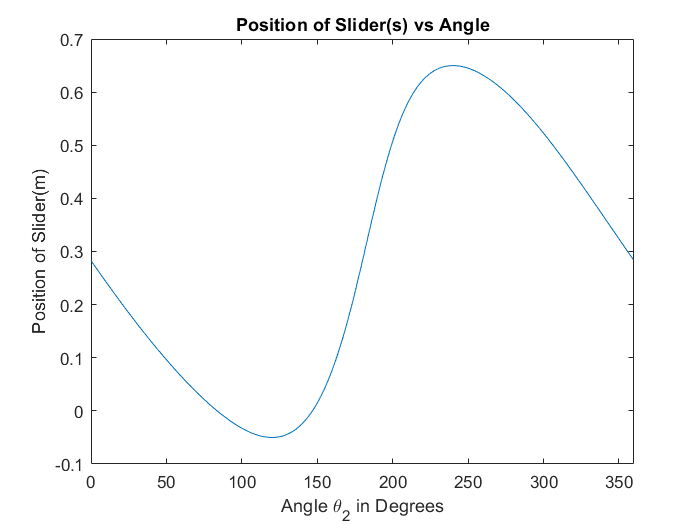

plot(X,S)

title('Position of Slider(s) vs Angle')
xlabel('Angle \theta_2 in Degrees')
ylabel('Position of Slider(m)')
xlim([0 360])

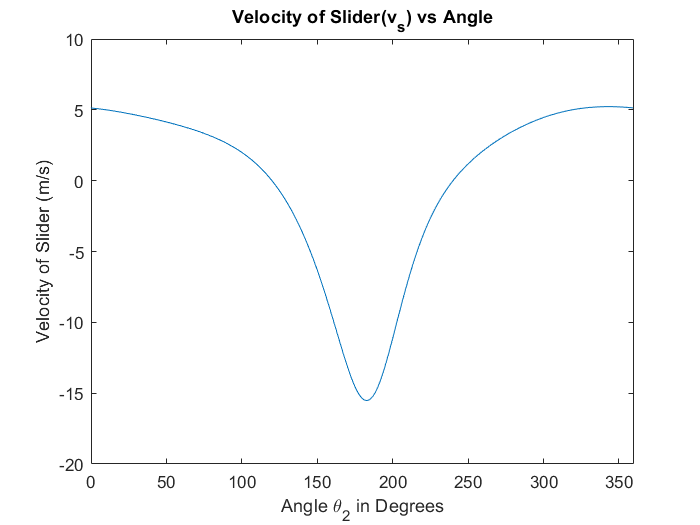



plot(X,S_1)
title('Velocity of Slider(v_s) vs Angle')
xlabel('Angle \theta_2 in Degrees')
ylabel('Velocity of Slider (m/s)')
xlim([0 360])

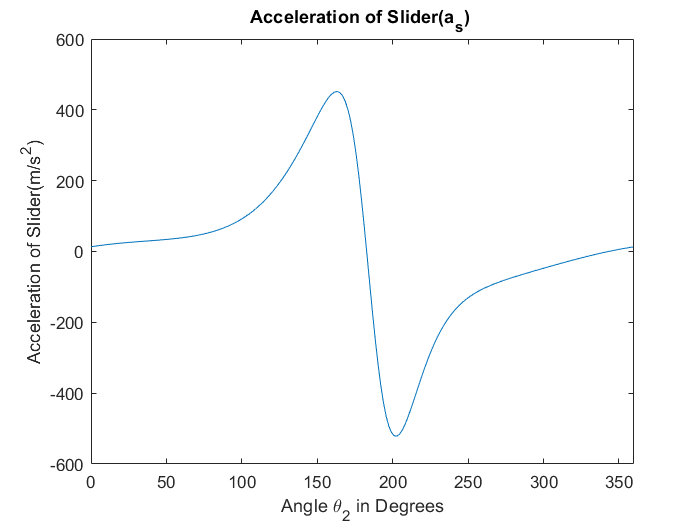


plot(X,S_2)
title('Acceleration of Slider(a_s) ')
xlabel('Angle \theta_2 in Degrees')
ylabel('Acceleration of Slider(m/s^2)')
xlim([0 360]) 

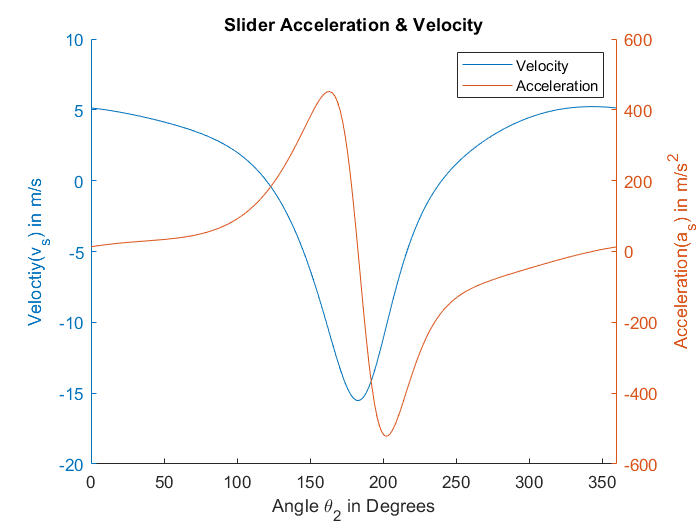

clf('reset')
hold on;
xlim([0,360]);

ylim([-20,10]);
yyaxis left;
plot(X,S_1);
yyaxis right;
plot(X,S_2);
yyaxis left
title('Slider Acceleration & Velocity')
xlabel('Angle \theta_2 in Degrees')
ylabel('Veloctiy(v_s) in m/s')
legend('Velocity','Acceleration')

yyaxis right
ylabel('Acceleration(a_s) in m/s^2')
hold off;

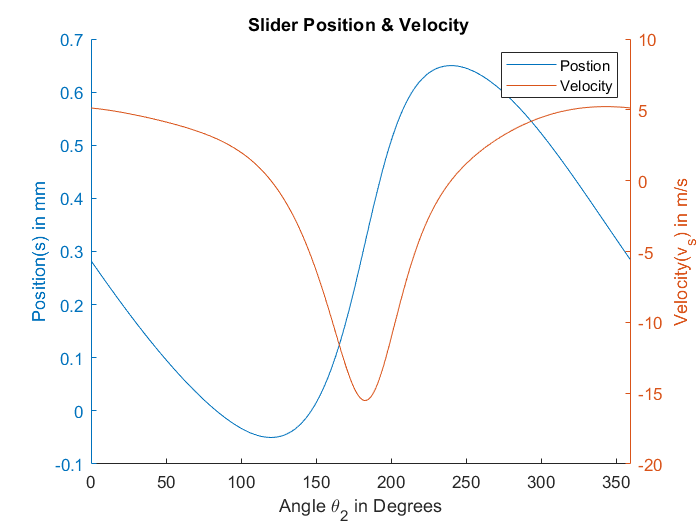

clf('reset')
hold on;
xlim([0,360]);
ylim([-100e-3,700e-3]);
yyaxis left;
plot(X,S); 

yyaxis right;
plot(X,S_1);
yyaxis left;

title('Slider Position & Velocity ')
xlabel('Angle \theta_2 in Degrees')
ylabel('Position(s) in mm')
legend('Postion','Velocity')
yyaxis right
ylabel('Velocity(v_s) in m/s')
hold off;

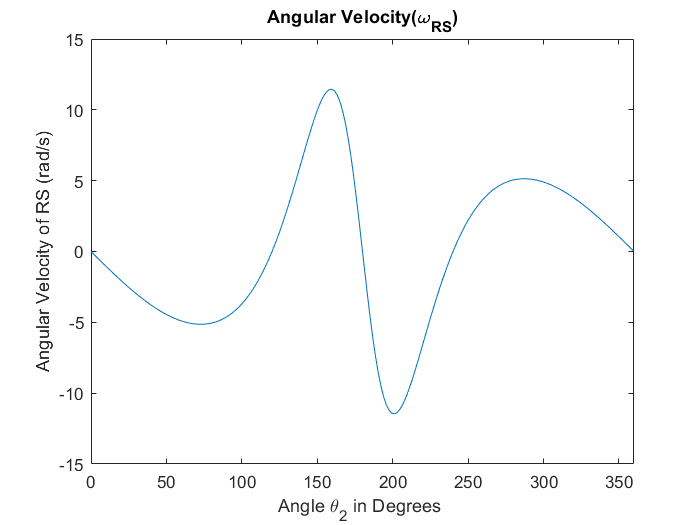

clf('reset')

plot(X,Omega_RS)
title('Angular Velocity(\omega_{RS})')
xlabel('Angle \theta_2 in Degrees ')
ylabel('Angular Velocity of RS (rad/s)')
xlim([0 360]) 

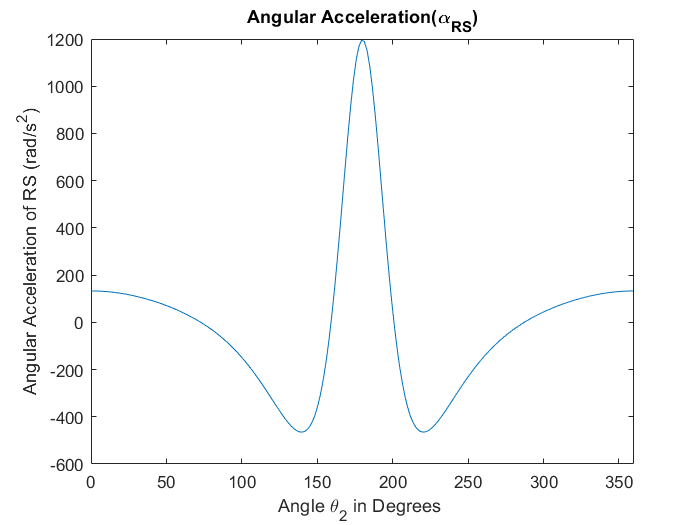

clf('reset')

plot(X,Alpha_RS)
title('Angular Acceleration(\alpha_{RS})')
xlabel('Angle \theta_2 in Degrees ')
ylabel('Angular Acceleration of RS (rad/s^2)')
xlim([0 360])

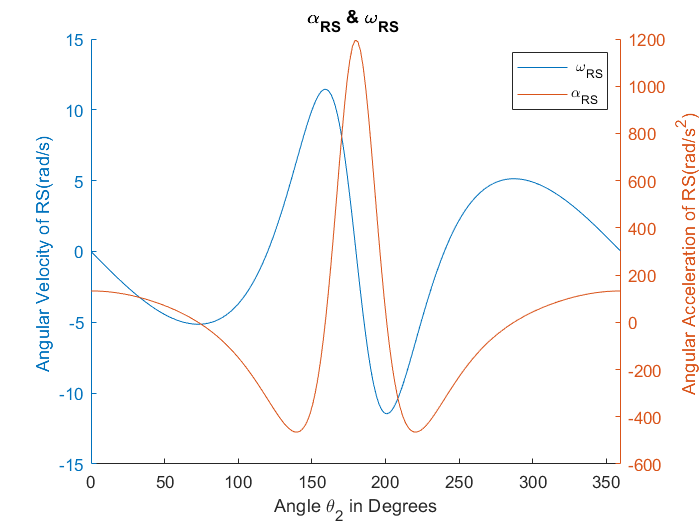

clf('reset')
hold on;
xlim([0,360]);
ylim([-15,+15]);
yyaxis left;
plot(X,Omega_RS); 

yyaxis right;
plot(X,Alpha_RS);
yyaxis left;

title('\alpha_{RS} & \omega_{RS} ')
xlabel('Angle \theta_2 in Degrees')
ylabel('Angular Velocity of RS(rad/s) ')
legend(' \omega_{RS}','\alpha_{RS}')
yyaxis right
ylabel('Angular Acceleration of RS(rad/s^2) ')
hold off;

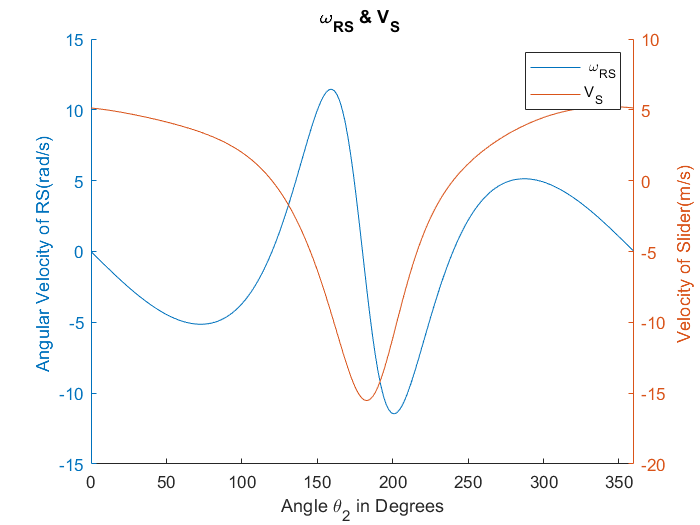

clf('reset')
hold on;
xlim([0,360]);
ylim([-15,+15]);
yyaxis left;
plot(X,Omega_RS); 

yyaxis right;
plot(X,S_1);
yyaxis left;

title('\omega_{RS} & V_{S} ')
xlabel('Angle \theta_2 in Degrees')
ylabel('Angular Velocity of RS(rad/s) ')
legend(' \omega_{RS}','V_{S}')
yyaxis right
ylabel('Velocity of Slider(m/s) ')
set(gca,'Fontsize',10);
hold off;

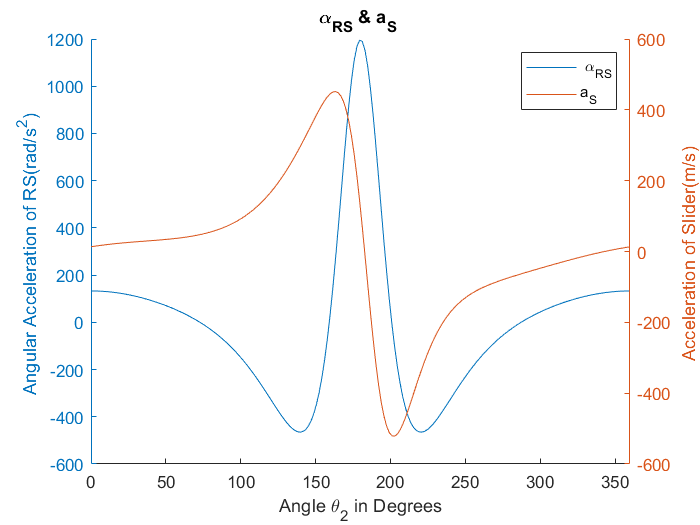

clf('reset')
hold on;
xlim([0,360]);

yyaxis left;
plot(X,Alpha_RS); 

yyaxis right;
plot(X,S_2);
yyaxis left;

title('\alpha_{RS} & a_{S} ')
xlabel('Angle \theta_2 in Degrees')
ylabel('Angular Acceleration of RS(rad/s^2) ')
legend(' \alpha_{RS}','a_{S}')
yyaxis right
ylabel('Acceleration of Slider(m/s) ')
set(gca,'Fontsize',10);

hold off;